## Autorregressive function

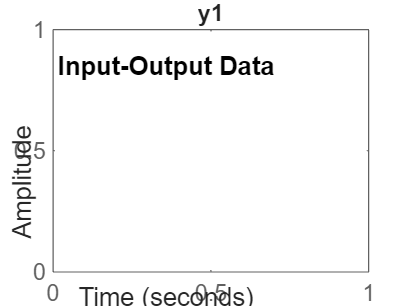

Operation terminated by user during iodatapack.iotimeplot/getfocus (line 16)

In iodatapack.iotimeplot/updatelims (line 17)
   set(ax(:,AutoX),'Xlim', getfocus(this));
In 

data = iddata(y(end-1000:end),[]);
sys = ar(data, 72);

K = 168;
p = forecast(sys, data, K);  
y_AR = p.OutputData;

t_forecast_AR = t(end) + duration(1:K, 0, 0)';

% Combine last 168 actual points + 168-step forecast
y_plot = [y(end-167:end); y_AR];                        % 2*168 points
t_plot = [t(end-167:end); t(end) + duration(1:K,0,0)']; % timestamps

figure;
plot(t_plot, y_plot, 'r');                       
hold on;
plot(t(end-167:end), y(end-167:end), 'b', 'LineWidth',1.5); 
title('Last 168 Actual Points and 168-Step AR Forecast');
xlabel('Time'); ylabel('Traffic Volume');
legend('Forecast','Last 168 Actual');
grid on;
